# Whale Travel Analysis

**Load Whale Data**

load cleanWhaleData.mat

id = "2008CA-Bmu-04176"

id = "2008CA-Bmu-04176"

whaleIndices = whales.ID == id

whaleIndices = 14514×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


whale = whales(whaleIndices,:)

whale = 259×8 table
           ID                  timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensorType         markedOutliers
    ________________    _______________________    _________    ________    _____________    __________________    ___________________    ______________

    2008CA-Bmu-04176    2008-07-28 00:40:25.000     -120.04      34.134           0                   5            argos-doppler-shift          ""      
    2008CA-Bmu-04176    2008-07-28 21:24:11.000     -120.61      34.115           0                   4            argos-doppler-shift          ""      
    2008CA-Bmu-04176    2008-07-29 21:11:49.000     -119.15      33.277           A            

**Calculate Total Distance**

lat = deg2rad(whale.latitude);
lon = deg2rad(whale.longitude);

R = 6371; % Earth radius in km

dlat = diff(lat);
dlon = diff(lon);


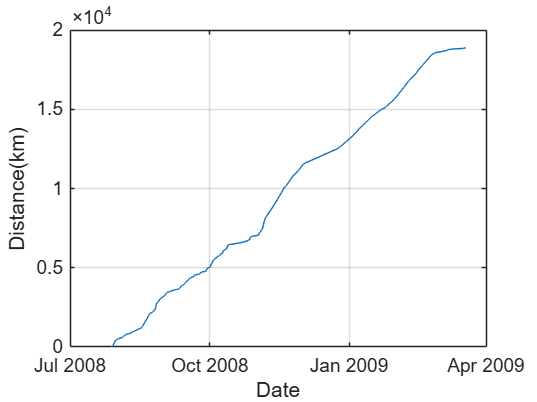

sin(dlat/2).^2 + cos(lat(1:end-1)).*cos(lat(2:end)).*sin(dlon/2).^2;
c = 2*atan2(sqrt(a), sqrt(1-a));

segmentDistance = R * c;

whale.distance = [0; cumsum(segmentDistance)];

plot(whale.timestamp,whale.distance)
xlabel("Date")
ylabel("Distance(km)")
grid on

**Calculate Elapsed Time**

whale.elapsedDays = days(whale.timestamp-whale.timestamp(1))

whale = 259×10 table
           ID                  timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensorType         markedOutliers    distance    elapsedDays
    ________________    _______________________    _________    ________    _____________    __________________    ___________________    ______________    ________    ___________

    2008CA-Bmu-04176    2008-07-28 00:40:25.000     -120.04      34.134           0                   5            argos-doppler-shift          ""                0             0  
    2008CA-Bmu-04176    2008-07-28 21:24:11.000     -120.61      34.115           0               

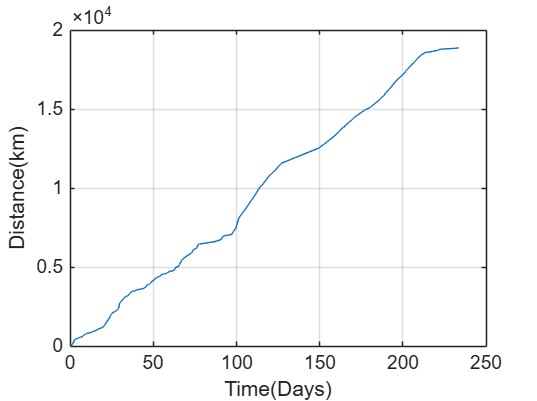


plot(whale.elapsedDays,whale.distance)
xlabel("Time(Days)")
ylabel("Distance(km)")
grid on

**Apply Linear Fit**

p = polyfit(whale.elapsedDays,whale.distance,1)

p =    85.3869 -158.9529



kmPerDay = p(1)

kmPerDay = 85.3869


whale.predictedDistance = polyval(p,whale.elapsedDays)

whale = 259×11 table
           ID                  timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensorType         markedOutliers    distance    elapsedDays    predictedDistance
    ________________    _______________________    _________    ________    _____________    __________________    ___________________    ______________    ________    ___________    _________________

    2008CA-Bmu-04176    2008-07-28 00:40:25.000     -120.04      34.134           0                   5            argos-doppler-shift          ""                0             0           -158.95     
 

**Visualize Linear Fit**

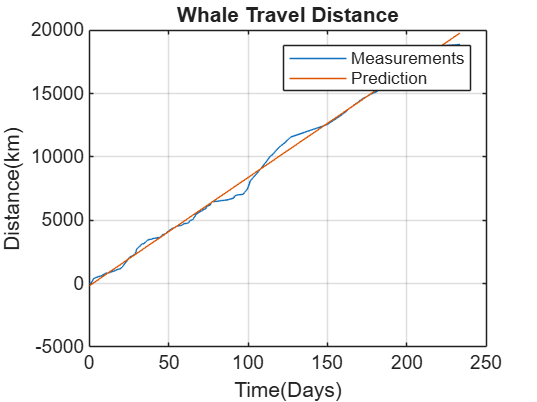

plot(whale.elapsedDays,whale.distance)
xlabel("Time(Days)")
ylabel("Distance(km)")
grid on

hold on
plot(whale.elapsedDays,whale.predictedDistance)
hold off

legend("Measurements","Prediction")
title("Whale Travel Distance")